%Create randomness
rng(1)

%Create a variable for the file path
datafolder = "C:\Users\leere\Desktop\Centrifugal Pump Sound";

%Use audioDatastore to easily manage the files
ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames');

%Visualising the 20th data in the audioDatastore
sig1 = audioread(ads.Files{20});

%Decomposition Tree
level = 2;
wpt = wpdec(sig1,level,'rbio2.8');
plot (wpt)

%plot the detail and approximation coefficient for the 20th signal in
%dataset
[c,l] = wavedec(sig1,3,'rbio2.8');
approx = appcoef(c,l,'rbio2.8');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);
subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')

% save Image to folder, and create the relevant subfolder
datafolder_scallogram = "datafolder/structure_Scallogram";
catego=categories(ads.Labels);
for i = 1:1:length(catego)
    imgLoc = fullfile(datafolder_scallogram,char(catego{i}));
    mkdir(imgLoc)
end

%Perform DWT feature extraction and convert to spectrogram and resize using
%this function
helperCreateRGBfromTF(ads,datafolder_scallogram)

%Load spectrograms into imageDatastore
allImages = imageDatastore(datafolder_scallogram,...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

%split spectrograms in a randomised process
rng(1)
[imgsTrain,imgsValidation,imgsTest] = splitEachLabel(allImages,0.6,0.2,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 540


countEachLabel(imgsTrain)

ans = 3×2 table
      Label       Count
    __________    _____

    Abnormal       180 
    Background     180 
    Normal         180 


disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

Number of validation images: 180


countEachLabel(imgsValidation)

ans = 3×2 table
      Label       Count
    __________    _____

    Abnormal       60  
    Background     60  
    Normal         60  


disp(['Number of validation images: ',num2str(numel(imgsTest.Files))]);

Number of validation images: 180


countEachLabel(imgsTest)

ans = 3×2 table
      Label       Count
    __________    _____

    Abnormal       60  
    Background     60  
    Normal         60  


imds = imageDatastore("C:\Users\leere\Documents\MATLAB\Examples\R2021a\deeplearning_shared\ClassifyLargeMultiresolutionImagesUsingDeepLearningExample\datafolder\structure_Scallogram\Abnormal\Abnormal_1.jpg")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\datafolder\structure_Scallogram\Abnormal\Abnormal_1.jpg'
                              }
                     Folders: {
                              ' ...\datafolder\structure_Scallogram\Abnormal'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


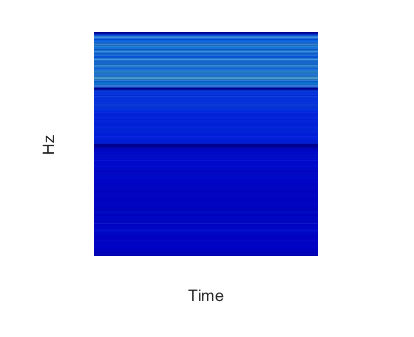

testim = readimage(imds,1);
imshow(testim)
xlabel ('Time'); ylabel ('Hz');

function helperCreateRGBfromTF(ads,datafolder_scallogram)

for i = 1:length(ads.Files)
    clearvars sig
   
    level=2;
    sig = audioread(ads.Files{i});
    cfs = abs(wavedec(sig(:),level,'rbio2.8'));
   
    im = ind2rgb(im2uint8(rescale(cfs)),jet(128));   
    imgLoc = fullfile(datafolder_scallogram,char(ads.Labels(i)));
    imFileName = strcat(char(ads.Labels(i)),'_',num2str(i),'.jpg');
    imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));
end
end